# Detection rates

# All subframe statistics - 30 s

Args.MagField = {'MAG_PSF'}; Args.MagErrField = {'MAGERR_PSF'};
Args.BadFlags = {'Saturated','Negative','NaN' ,'Spike','Hole','CR_DeltaHT','NearEdge'};
Args.EdgeFlags = {'Overlap'};
Args.runMeanFilterArgs      = {'Threshold',5, 'StdFun','OutWin'};
Args.Nvisits = 1;
Args.Ndet = 16*Args.Nvisits;

true;%Load data
cd('/Users/yarinms/marvin/LAST.01.05.03/2024/08/07/proc')
List = MatchedSources.rdirMatchedSourcesSearch('FileTemplate','*.hdf5');

FN = 'WDJ19174';
if exist("List","var")
    flag =1;
end

false

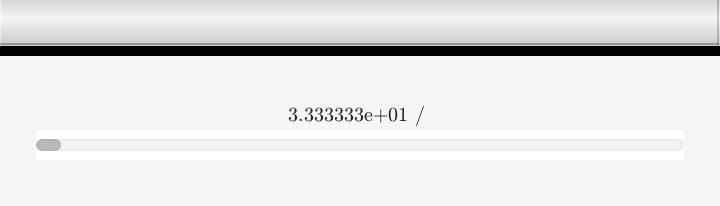

Elapsed time is 5.472248 seconds.


Unrecognized function or variable 'detect3'.

list = List;
Args.Ndet = 16*Args.Nvisits;
 mB17_175 =zeros(24,6);
 mB175_18 =zeros(24,6);
 mB18_185 =zeros(24,6);
 mB185_19 =zeros(24,6);
 mB19_195 =zeros(24,6);
 mB1195=zeros(24,6);
 FRD1=zeros(24,1);
 FRD2=zeros(24,1);
 FRD3=zeros(24,1);

  nB17_175 =zeros(24,6);
 nB175_18 =zeros(24,6);
 nB18_185 =zeros(24,6);
 nB185_19 =zeros(24,6);
 nB19_195 =zeros(24,6);
 nB1195=zeros(24,6);


Fap =zeros(24,6);
allSrcStat = zeros(24,6);
allSrcN = zeros(24,6);
h = waitbar(0);
detEff = [];
mEff = [];
AllFap = [];
AllS = 0;
tic
for Iid = 1:24 

 tic

    list1.FileName = List(Iid).FileName(contains(List(Iid).FileName,FN));
    list1.Folder   = List(Iid).Folder(contains(List(Iid).FileName,FN));
    list1.CropID = List(Iid).CropID;
    ms1 =  MatchedSources.readList(list1);
    Nvis = length(ms1);

toc
    for Ivis = 1: length(ms1)
    

        MMS = ms1(Ivis).setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
        R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
        [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
        % Remove sources with NdetGood<MinNdet
        NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);

        Fndet    = NdetGood>Args.Ndet;

        % Fndet  = Fndet & (mean(MMS.Data.MAG_PSF,'omitnan') < 19.5);
        allSrc  = MMS.Nsrc;
        goodSrc = sum(Fndet);
        allSrcStat(Iid,Ivis) = goodSrc/allSrc;
        allSrcN(Iid,Ivis) = allSrc;

        % MagBinStat
        flag1 = mean(MMS.Data.MAG_PSF,'omitnan') > 17 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.5;
        mB17_175(Iid,Ivis) = sum(Fndet & flag1)/sum(flag1);
        flag2 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 18;
        mB175_18(Iid,Ivis) = sum(Fndet & flag2)/sum(flag2);
        flag3 = mean(MMS.Data.MAG_PSF,'omitnan') > 18 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.5;
        mB18_185(Iid,Ivis) = sum(Fndet & flag3)/sum(flag3);
        flag4 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 19;
        mB185_19(Iid,Ivis) = sum(Fndet & flag4)/sum(flag4);
        flag5 = mean(MMS.Data.MAG_PSF,'omitnan') > 19 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.5;
        mB19_195(Iid,Ivis) = sum(Fndet & flag5)/sum(flag5);
        flag6 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.5 ;
        mB1195(Iid,Ivis) = sum(Fndet & flag6)/sum(flag6);

        
        nB17_175(Iid,Ivis) = sum(flag1);
       
        nB175_18(Iid,Ivis) = sum(flag2);

        nB18_185(Iid,Ivis) = sum(flag3);

        nB185_19(Iid,Ivis) = sum(flag4);

        nB19_195(Iid,Ivis) = sum(flag5);

        nB1195(Iid,Ivis) = sum(flag6);
        

        indices = find(flag1 == 1);


        MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);

        light_curves = MMS.Data.MAG_PSF;
        [Nan,consecutive_nan_indices,FAP,mFap,Si,T] = X.find_similar_nan_patterns(light_curves);

        % Nan Count:
        M = median(light_curves,'omitnan')';
        N = sum(isnan(light_curves(:,:)));

        AllFap = [AllFap ; M(logical(FAP))];
        AllS   = AllS+numel(M);


        Npts = MMS.Nepoch;
        detEff = [detEff;1 - N'/Npts];
        mEff = [mEff;M];
        c=0;
        for j = 1 : size(Nan,2)
            c = c + length(Nan{1,j}{1}{2});
        end

        Fap(Iid,Ivis)   = sum(FAP)/length(light_curves(1,:));
        MFap(Iid,Ivis)  = sum(sum(mFap))/(2* length(FAP));
        t(Iid,Ivis)     = T;

        if Ivis == 4
        [fDetection1,fDetection2,fDetection3] = detect3(MMS);
          

        FRD1(Iid,Ivis) = size(fDetection1,1)/MMS.Nsrc;
        FRD2(Iid,Ivis) = size(fDetection2,1)/MMS.Nsrc;
        FRD3(Iid,Ivis) = size(fDetection3,1)/MMS.Nsrc;
        end
     


        
     waitbar(Iid/24,h,sprintf('%i / %i Visits analayzed',(Iid*Ivis),(24*Nvis)))

    end

 



end

close(h)
toc





fprintf('The False Positive rate as a result of minimum 2 consecutive NaNs in a 30s exposure :%.4f',mean(mean(Fap(:,3:end))))

The False Positive rate as a result of minimum 2 consecutive NaNs in a 30s exposure :0.0114

fprintf('Out of these events, %.4f appear in control group stars',mean(mean(MFap(:,3:end),'omitnan')))

Out of these events, 0.0019 appear in control group stars

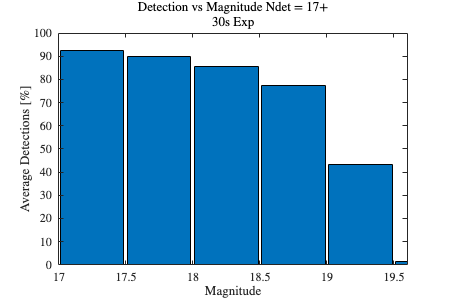




binEdges = linspace(17.0,20, 30);
binEfficiencies(1) = median(median(mB17_175))*100;
binEfficiencies(2) = median(median(mB175_18))*100;
binEfficiencies(3) = median(median(mB18_185))*100;
binEfficiencies(4) = median(median(mB185_19))*100;
binEfficiencies(5) = median(median(mB19_195))*100;
binEfficiencies(6) = median(median(mB1195))*100;



binCenters =[17.25,17.75,18.25,18.75,19.25,19.75];



% Plot the histogram
figure('Position', [100, 100, 600, 400]);
bar(binCenters, binEfficiencies,"BarWidth",0.95,"BarLayout","stacked");
xlabel('Magnitude');
ylabel('Average Detections [%]');
title(sprintf('Detection vs Magnitude Ndet = 17+\n 30s Exp'));
xlim([17,19.6])


fprintf('All sources in all visits:')

All sources in all visits:

fprintf('%.2f%% out of %i sources survived ',median(median(allSrcStat))*100,sum(sum(allSrcN)))

68.71% out of 2203663 sources survived 


$$17<M<17\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB17_175))*100,sum(sum(nB17_175)))

92.59% out of 196947 sources survived 


$$17\ldotp 5<M<18$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB175_18))*100,sum(sum(nB175_18)))

89.78% out of 231279 sources survived 


$$18<M<18\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB18_185))*100,sum(sum(nB18_185)))

85.65% out of 259062 sources survived 


$$18\ldotp 5<M<19$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB185_19))*100,sum(sum(nB185_19)))

77.15% out of 270073 sources survived 


$$19<M<19\ldotp 5$$


fprintf('%.2f%% of %i sources survived ',median(median(mB19_195))*100,sum(sum(nB19_195)))

43.33% of 350133 sources survived 


$$19\ldotp 5<M$$


fprintf('%.2f%% of  %i sources survived ',median(median(mB1195))*100,sum(sum(nB1195)))

1.25% of  238061 sources survived 

## NAN FPR frequency VS mag

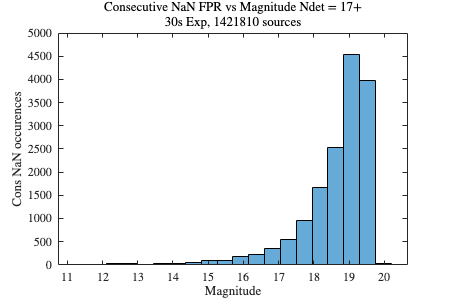

% Plot the histogram
V =AllFap;
figure('Position', [100, 100, 600, 400]);
histogram(V,20);
xlabel('Magnitude');
ylabel('Cons NaN occurences');
title(sprintf('Consecutive NaN FPR vs Magnitude Ndet = 17+\n 30s Exp, %i sources',AllS));

%xlim([12,20])
%ylim([0,0.0002])

### Detection  methods FPR

taking a visit from sunframe. applying detection method on all sources while scrambling the data

Where Method 1 is 2 consecutive deviating data points

method 2 is run mean filter with threshold = 5 and window = 2

method 3 is Area detrction

and "Method" 4 is the occurence of consecutive nans within the data.

FPv = [ mean(FRD1(:,4));mean(FRD2(:,4));mean(FRD2(:,4));mean(mean(Fap(:,3:end))) ]

FPv =      0.011869
    0.0029982
    0.0029982
     0.011385


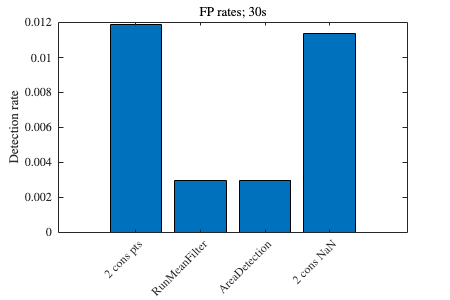

figure('Position', [100, 100, 600, 400]);
bar(FPv)
labels = {'2 cons pts', 'RunMeanFilter', 'AreaDetection', '2 cons NaN', 'Elderberry'};
xticks(1:length(FPv));


xticklabels(labels);
xtickangle(45); 
ylabel('Detection rate')
title('FP rates; 30s')

# All subframe statistics - 40 s

cd('/Users/yarinms/marvin/LAST.01.04.03/2024/08/07/proc')
List = MatchedSources.rdirMatchedSourcesSearch('FileTemplate','*.hdf5');

FN = 'DZ19M';
if exist("List","var")
    flag =1;
end

false

ans = logical
   0

list = List;
Args.Ndet = 16*Args.Nvisits;
 mB17_175 =zeros(24,6);
 mB175_18 =zeros(24,6);
 mB18_185 =zeros(24,6);
 mB185_19 =zeros(24,6);
 mB19_195 =zeros(24,6);
 mB1195=zeros(24,6);
 FRD1=zeros(24,1);
 FRD2=zeros(24,1);
 FRD3=zeros(24,1);

  nB17_175 =zeros(24,6);
 nB175_18 =zeros(24,6);
 nB18_185 =zeros(24,6);
 nB185_19 =zeros(24,6);
 nB19_195 =zeros(24,6);
 nB1195=zeros(24,6);


Fap =zeros(24,6);
allSrcStat = zeros(24,6);
allSrcN = zeros(24,6);
h = waitbar(0);
detEff = [];
mEff = [];
AllFap = [];
AllS = 0;
tic
for Iid = 1:24 



    list1.FileName = List(Iid).FileName(contains(List(Iid).FileName,FN));
    list1.Folder   = List(Iid).Folder(contains(List(Iid).FileName,FN));
    list1.CropID = List(Iid).CropID;
    ms1 =  MatchedSources.readList(list1);
    Nvis = length(ms1);


    for Ivis = 1: length(ms1)
    

        MMS = ms1(Ivis).setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
        R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
        [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
        % Remove sources with NdetGood<MinNdet
        NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);

        Fndet    = NdetGood>Args.Ndet;

        % Fndet  = Fndet & (mean(MMS.Data.MAG_PSF,'omitnan') < 19.5);
        allSrc  = MMS.Nsrc;
        goodSrc = sum(Fndet);
        allSrcStat(Iid,Ivis) = goodSrc/allSrc;
        allSrcN(Iid,Ivis) = allSrc;

        % MagBinStat
        flag1 = mean(MMS.Data.MAG_PSF,'omitnan') > 17 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.5;
        mB17_175(Iid,Ivis) = sum(Fndet & flag1)/sum(flag1);
        flag2 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 18;
        mB175_18(Iid,Ivis) = sum(Fndet & flag2)/sum(flag2);
        flag3 = mean(MMS.Data.MAG_PSF,'omitnan') > 18 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.5;
        mB18_185(Iid,Ivis) = sum(Fndet & flag3)/sum(flag3);
        flag4 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 19;
        mB185_19(Iid,Ivis) = sum(Fndet & flag4)/sum(flag4);
        flag5 = mean(MMS.Data.MAG_PSF,'omitnan') > 19 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.5;
        mB19_195(Iid,Ivis) = sum(Fndet & flag5)/sum(flag5);
        flag6 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.5 ;
        mB1195(Iid,Ivis) = sum(Fndet & flag6)/sum(flag6);

        
        nB17_175(Iid,Ivis) = sum(flag1);
       
        nB175_18(Iid,Ivis) = sum(flag2);

        nB18_185(Iid,Ivis) = sum(flag3);

        nB185_19(Iid,Ivis) = sum(flag4);

        nB19_195(Iid,Ivis) = sum(flag5);

        nB1195(Iid,Ivis) = sum(flag6);
        

        indices = find(flag1 == 1);


        MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);

        light_curves = MMS.Data.MAG_PSF;
        [Nan,consecutive_nan_indices,FAP,mFap,Si,T] = X.find_similar_nan_patterns(light_curves);

        % Nan Count:
        M = median(light_curves,'omitnan')';
        N = sum(isnan(light_curves(:,:)));

        AllFap = [AllFap ; M(logical(FAP))];
        AllS   = AllS+numel(M);


        Npts = MMS.Nepoch;
        detEff = [detEff;1 - N'/Npts];
        mEff = [mEff;M];
        c=0;
        for j = 1 : size(Nan,2)
            c = c + length(Nan{1,j}{1}{2});
        end

        Fap(Iid,Ivis)   = sum(FAP)/length(light_curves(1,:));
        MFap(Iid,Ivis)  = sum(sum(mFap))/(2* length(FAP));
        t(Iid,Ivis)     = T;

        if Ivis == 4
        [fDetection1,fDetection2,fDetection3] = detect3(MMS);
          

        FRD1(Iid,1) = size(fDetection1,1)/MMS.Nsrc;
        FRD2(Iid,1) = size(fDetection2,1)/MMS.Nsrc;
        FRD3(Iid,1) = size(fDetection3,1)/MMS.Nsrc;
        end
     


        
     waitbar(Iid/24,h,sprintf('%i / %i Visits analayzed',(Iid*Ivis),(24*Nvis)))

    end

 



end
close(h)
toc

Elapsed time is 1356.065320 seconds.




fprintf('The False Positive rate as a result of minimum 2 consecutive NaNs in a 40s exposure :%.4f',mean(mean(Fap(:,3:end))))

The False Positive rate as a result of minimum 2 consecutive NaNs in a 40s exposure :0.0194

fprintf('Out of these events, %.4f appear in control group stars',mean(mean(MFap(:,3:end),'omitnan')))

Out of these events, 0.0248 appear in control group stars

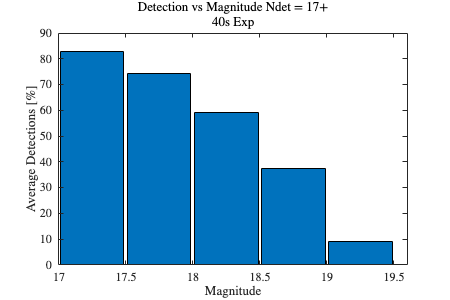




binEdges = linspace(17.0,20, 30);
binEfficiencies(1) = median(median(mB17_175))*100;
binEfficiencies(2) = median(median(mB175_18))*100;
binEfficiencies(3) = median(median(mB18_185))*100;
binEfficiencies(4) = median(median(mB185_19))*100;
binEfficiencies(5) = median(median(mB19_195,'omitnan'))*100;
binEfficiencies(6) = median(median(mB1195))*100;



binCenters =[17.25,17.75,18.25,18.75,19.25,19.75];



% Plot the histogram
figure('Position', [100, 100, 600, 400]);
bar(binCenters, binEfficiencies,"BarWidth",0.95,"BarLayout","stacked");
xlabel('Magnitude');
ylabel('Average Detections [%]');
title(sprintf('Detection vs Magnitude Ndet = 17+\n 40s Exp'));
xlim([17,19.6])


fprintf('All sources in all visits:')

All sources in all visits:

fprintf('%.2f%% out of %i sources survived ',median(median(allSrcStat))*100,sum(sum(allSrcN)))

64.37% out of 4934973 sources survived 


$$17<M<17\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB17_175))*100,sum(sum(nB17_175)))

82.94% out of 594967 sources survived 


$$17\ldotp 5<M<18$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB175_18))*100,sum(sum(nB175_18)))

74.21% out of 676228 sources survived 


$$18<M<18\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB18_185))*100,sum(sum(nB18_185)))

59.25% out of 692983 sources survived 


$$18\ldotp 5<M<19$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB185_19))*100,sum(sum(nB185_19)))

37.53% out of 642125 sources survived 


%fprintf('9.97% of %i sources survived ',sum(sum(nB19_195)))

%fprintf('0% of  %i sources survived ',sum(sum(nB1195)))

## NAN FPR frequency VS mag

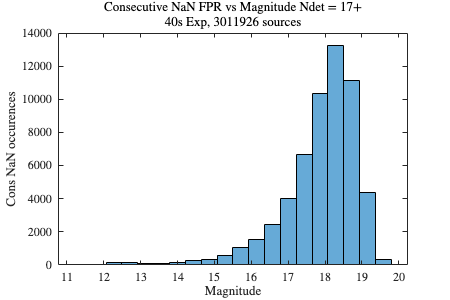

% Plot the histogram
V =AllFap;
figure('Position', [100, 100, 600, 400]);
histogram(V,20);
xlabel('Magnitude');
ylabel('Cons NaN occurences');
title(sprintf('Consecutive NaN FPR vs Magnitude Ndet = 17+\n 40s Exp, %i sources',AllS));

%xlim([12,20])
%ylim([0,0.0002])

### Detection  methods FPR

taking a visit from sunframe. applying detection method on all sources while scrambling the data

Where Method 1 is 2 consecutive deviating data points

method 2 is run mean filter with threshold = 5 and window = 2

method 3 is Area detrction

and "Method" 4 is the occurence of consecutive nans within the data.

FPv = [ mean(FRD1(:,4));mean(FRD2(:,4));mean(FRD2(:,4));mean(mean(Fap(:,3:end))) ]

FPv =      0.022885
    0.0052048
    0.0052048
     0.019437


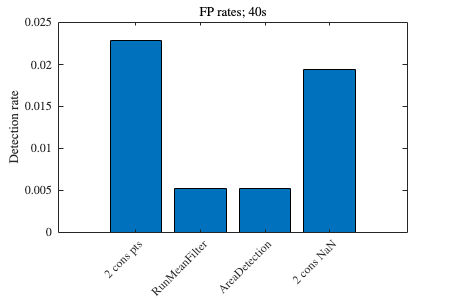

figure('Position', [100, 100, 600, 400]);
bar(FPv)
labels = {'2 cons pts', 'RunMeanFilter', 'AreaDetection', '2 cons NaN', 'Elderberry'};
xticks(1:length(FPv));


xticklabels(labels);
xtickangle(45); 
ylabel('Detection rate')
title('FP rates; 40s')

# All subframe statistics - 20 s

cd('/Users/yarinms/marvin/LAST.01.10.03/2024/08/07/proc')
List = MatchedSources.rdirMatchedSourcesSearch('FileTemplate','*.hdf5');

FN = '1127';
if exist("List","var")
    flag =1;
end


list = List;
Args.Ndet = 16*Args.Nvisits;
 mB17_175 =zeros(24,6);
 mB175_18 =zeros(24,6);
 mB18_185 =zeros(24,6);
 mB185_19 =zeros(24,6);
 mB19_195 =zeros(24,6);
 mB1195=zeros(24,6);
 FRD1=zeros(24,1);
 FRD2=zeros(24,1);
 FRD3=zeros(24,1);

  nB17_175 =zeros(24,6);
 nB175_18 =zeros(24,6);
 nB18_185 =zeros(24,6);
 nB185_19 =zeros(24,6);
 nB19_195 =zeros(24,6);
 nB1195=zeros(24,6);


Fap =zeros(24,6);
allSrcStat = zeros(24,6);
allSrcN = zeros(24,6);
h = waitbar(0);
detEff = [];
mEff = [];
AllFap = [];
AllS = 0;
tic
for Iid = 1:24 



    list1.FileName = List(Iid).FileName(contains(List(Iid).FileName,FN));
    list1.Folder   = List(Iid).Folder(contains(List(Iid).FileName,FN));
    list1.CropID = List(Iid).CropID;
    ms1 =  MatchedSources.readList(list1);
    Nvis = length(ms1);


    for Ivis = 1: 2 %length(ms1)
    

        MMS = ms1(Ivis).setBadPhotToNan('BadFlags',Args.BadFlags, 'MagField','MAG_PSF', 'CreateNewObj',true);
        R = lcUtil.zp_meddiff(MMS,'MagField',Args.MagField,'MagErrField',Args.MagErrField);
        [MMS,ApplyToMagFieldr] = applyZP(MMS, R.FitZP,'ApplyToMagField',Args.MagField);
        % Remove sources with NdetGood<MinNdet
        NdetGood = sum(~isnan(MMS.Data.MAG_PSF), 1);

        Fndet    = NdetGood>Args.Ndet;

        % Fndet  = Fndet & (mean(MMS.Data.MAG_PSF,'omitnan') < 19.5);
        allSrc  = MMS.Nsrc;
        goodSrc = sum(Fndet);
        allSrcStat(Iid,Ivis) = goodSrc/allSrc;
        allSrcN(Iid,Ivis) = allSrc;

        % MagBinStat
        flag1 = mean(MMS.Data.MAG_PSF,'omitnan') > 17 & mean(MMS.Data.MAG_PSF,'omitnan') < 17.5;
        mB17_175(Iid,Ivis) = sum(Fndet & flag1)/sum(flag1);
        flag2 = mean(MMS.Data.MAG_PSF,'omitnan') > 17.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 18;
        mB175_18(Iid,Ivis) = sum(Fndet & flag2)/sum(flag2);
        flag3 = mean(MMS.Data.MAG_PSF,'omitnan') > 18 & mean(MMS.Data.MAG_PSF,'omitnan') < 18.5;
        mB18_185(Iid,Ivis) = sum(Fndet & flag3)/sum(flag3);
        flag4 = mean(MMS.Data.MAG_PSF,'omitnan') > 18.5 & mean(MMS.Data.MAG_PSF,'omitnan') < 19;
        mB185_19(Iid,Ivis) = sum(Fndet & flag4)/sum(flag4);
        flag5 = mean(MMS.Data.MAG_PSF,'omitnan') > 19 & mean(MMS.Data.MAG_PSF,'omitnan') < 19.5;
        mB19_195(Iid,Ivis) = sum(Fndet & flag5)/sum(flag5);
        flag6 = mean(MMS.Data.MAG_PSF,'omitnan') > 19.5 ;
        mB1195(Iid,Ivis) = sum(Fndet & flag6)/sum(flag6);

        
        nB17_175(Iid,Ivis) = sum(flag1);
       
        nB175_18(Iid,Ivis) = sum(flag2);

        nB18_185(Iid,Ivis) = sum(flag3);

        nB185_19(Iid,Ivis) = sum(flag4);

        nB19_195(Iid,Ivis) = sum(flag5);

        nB1195(Iid,Ivis) = sum(flag6);
        

        indices = find(flag1 == 1);


        MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);

        light_curves = MMS.Data.MAG_PSF;
        [Nan,consecutive_nan_indices,FAP,mFap,Si,T] = X.find_similar_nan_patterns(light_curves);

        % Nan Count:
        M = median(light_curves,'omitnan')';
        N = sum(isnan(light_curves(:,:)));

        AllFap = [AllFap ; M(logical(FAP))];
        AllS   = AllS+numel(M);


        Npts = MMS.Nepoch;
        detEff = [detEff;1 - N'/Npts];
        mEff = [mEff;M];
        c=0;
        for j = 1 : size(Nan,2)
            c = c + length(Nan{1,j}{1}{2});
        end

        Fap(Iid,Ivis)   = sum(FAP)/length(light_curves(1,:));
        MFap(Iid,Ivis)  = sum(sum(mFap))/(2* length(FAP));
        t(Iid,Ivis)     = T;

        if Ivis == 2
        [fDetection1,fDetection2,fDetection3] = detect3(MMS);
          

        FRD1(Iid,1) = size(fDetection1,1)/MMS.Nsrc;
        FRD2(Iid,1) = size(fDetection2,1)/MMS.Nsrc;
        FRD3(Iid,1) = size(fDetection3,1)/MMS.Nsrc;
        end
     


        
     waitbar(Iid/24,h,sprintf('%i / %i Visits analayzed',(Iid*Ivis),(24*Nvis)))

    end

 



end
close(h)
toc

Elapsed time is 534.602045 seconds.




fprintf('The False Positive rate as a result of minimum 2 consecutive NaNs in a 20s exposure :%.4f',mean(mean(Fap(:,1:2))))

The False Positive rate as a result of minimum 2 consecutive NaNs in a 20s exposure :0.0119

fprintf('Out of these events, %.4f appear in control group stars',mean(mean(MFap(:,1:2),'omitnan')))

Out of these events, 0.0016 appear in control group stars

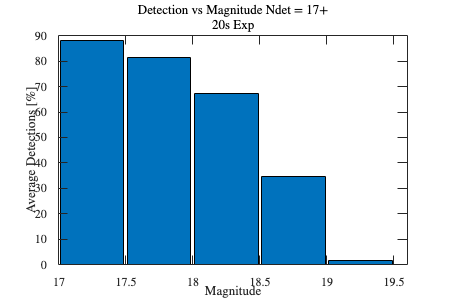




binEdges = linspace(17.0,20, 30);
binEfficiencies(1) = median(median(mB17_175(:,1:2)))*100;
binEfficiencies(2) = median(median(mB175_18(:,1:2)))*100;
binEfficiencies(3) = median(median(mB18_185(:,1:2)))*100;
binEfficiencies(4) = median(median(mB185_19(:,1:2)))*100;
binEfficiencies(5) = median(median(mB19_195(:,1:2)))*100;
binEfficiencies(6) = median(median(mB1195(:,1:2)))*100;



binCenters =[17.25,17.75,18.25,18.75,19.25,19.75];



% Plot the histogram
figure('Position', [100, 100, 600, 400]);
bar(binCenters, binEfficiencies,"BarWidth",0.95,"BarLayout","stacked");
xlabel('Magnitude');
ylabel('Average Detections [%]');
title(sprintf('Detection vs Magnitude Ndet = 17+\n 20s Exp'));
xlim([17,19.6])


fprintf('All sources in all visits:')

All sources in all visits:

fprintf('%.2f%% out of %i sources survived ',median(median(allSrcStat))*100,sum(sum(allSrcN(:,1:2))))

0.00% out of 380353 sources survived 


$$17<M<17\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB17_175))*100,sum(sum(nB17_175(:,1:2))))

0.00% out of 42732 sources survived 


$$17\ldotp 5<M<18$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB175_18))*100,sum(sum(nB175_18(:,1:2))))

0.00% out of 50408 sources survived 


$$18<M<18\ldotp 5$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB18_185))*100,sum(sum(nB18_185(:,1:2))))

0.00% out of 56585 sources survived 


$$18\ldotp 5<M<19$$


fprintf('%.2f%% out of %i sources survived ',median(median(mB185_19))*100,sum(sum(nB185_19(:,1:2))))

0.00% out of 66950 sources survived 


$$19<M<19\ldotp 5$$


fprintf('%.2f%% of %i sources survived ',median(median(mB19_195))*100,sum(sum(nB19_195(:,1:2))))

0.00% of 30854 sources survived 


$$19\ldotp 5<M$$


fprintf('%.2f%% of  %i sources survived ',median(median(mB1195))*100,sum(sum(nB1195(:,1:2))))

0.00% of  1630 sources survived 

## NAN FPR frequency VS mag

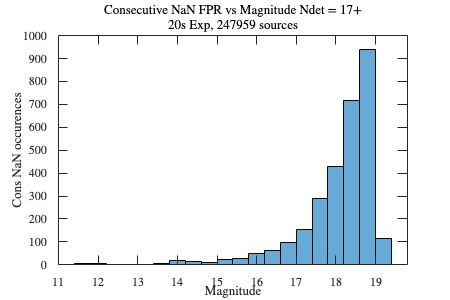

% Plot the histogram
V =AllFap;
figure('Position', [100, 100, 600, 400]);
histogram(V,20);
xlabel('Magnitude');
ylabel('Cons NaN occurences');
title(sprintf('Consecutive NaN FPR vs Magnitude Ndet = 17+\n 20s Exp, %i sources',AllS));

%xlim([12,20])
%ylim([0,0.0002])

### Detection  methods FPR

taking a visit from sunframe. applying detection method on all sources while scrambling the data

Where Method 1 is 2 consecutive deviating data points

method 2 is run mean filter with threshold = 5 and window = 2

method 3 is Area detrction

and "Method" 4 is the occurence of consecutive nans within the data.

FPv = [ mean(FRD1(:,1));mean(FRD2(:,1));mean(FRD2(:,1));mean(mean(Fap(:,1:2))) ]

FPv =     0.0094318
    0.0019119
    0.0019119
     0.011935


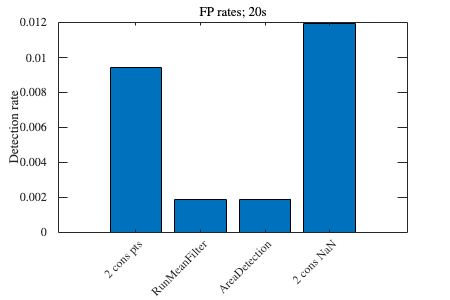

figure('Position', [100, 100, 600, 400]);
bar(FPv)
labels = {'2 cons pts', 'RunMeanFilter', 'AreaDetection', '2 cons NaN', 'Elderberry'};
xticks(1:length(FPv));


xticklabels(labels);
xtickangle(45); 
ylabel('Detection rate')
title('FP rates; 20s')